## Load Data

% cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\SupportingInformation\Groundwater\MATLAB\Products'

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Groundwater'
cd BarometricEfficiency\data\input\

load('BLM93.mat')
load('BLM93A.mat')
load('BLM93C.mat')
load('BLM64.mat')
load('BLM63.mat')
load('BLM53B.mat')
load('BLM53.mat')
load('BLM50B.mat')
load('BLM45.mat')
load('BLM43A.mat')
load('BLM41.mat')  
load('BLM37.mat')  
load('BLM34.mat')  
load('BLM31.mat')
load('BLM16.mat')
load('BLM16A.mat')
load('BLM12.mat')
    BLM12 = sortrows(BLM12,'WaterLevelBelowSurface_m','ascend');
    BLM12(27044:55298,:) = []; %remove empty rows

load('Bflat30min.mat')
Bflat30min = removevars(Bflat30min, {'NetRad_Wm2','AirTemp2_C','RelHumidity','WindSpeed_kph','WindDirection_Degrees','WindGust_kph','PPT_mm','NetRad_sw_Wm2','SolarRad_Wm2','NetRad_lw_Wm2','OutRad_sw_Wm2','OutRad_lw_Wm2','InRad_lw_Wm2','timeMDT'});

## BLM93C Barometric Efficiency 

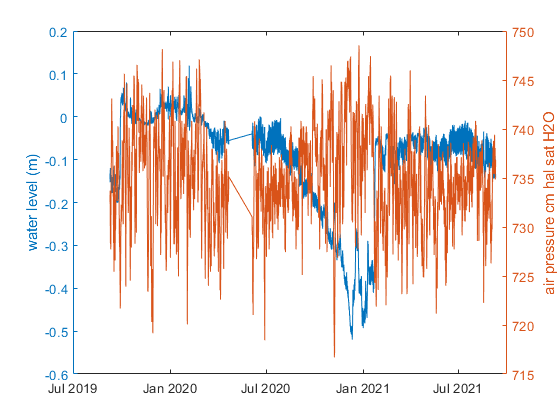

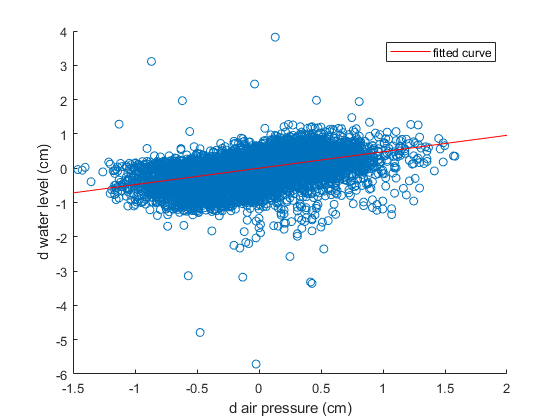

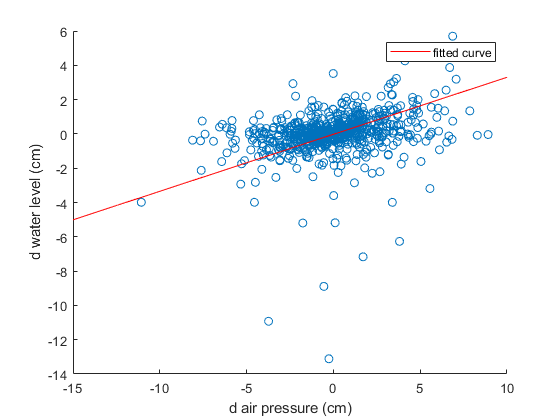

BLM93C_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

            0.5203                       0.21882                    0.51946                0.86435                     0.13039                  0.86132          93.3 


% (Daily Values Only) (Not using, over-corrected values - and not consistent acress time intervals). Linear regression method
load('BLM93C.mat')
BLM93C = WellGradientCalculaton(BLM93C,Bflat30min); 
BLM93C_BaroEff = BaroEff(BLM93C, 93.3)

%%Correction to BLM93C DTW values - will not use, overcorrects
% mean(table2array(BLM93C_BaroEff(1,[1 3 4 6])))
BLM93C_BaroEff.BaroEff = 1

BLM93C_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

            0.5203                       0.21882                    0.51946                0.86435                     0.13039                  0.86132          93.3        1   


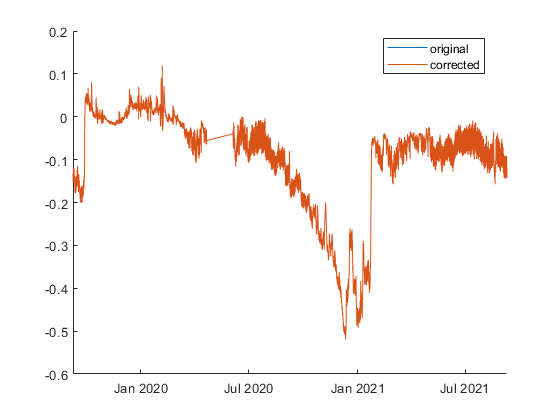

BLM93C =  BaroCorrection(BLM93C, BLM93C_BaroEff.BaroEff);

## BLM93 Barometric Efficiency 

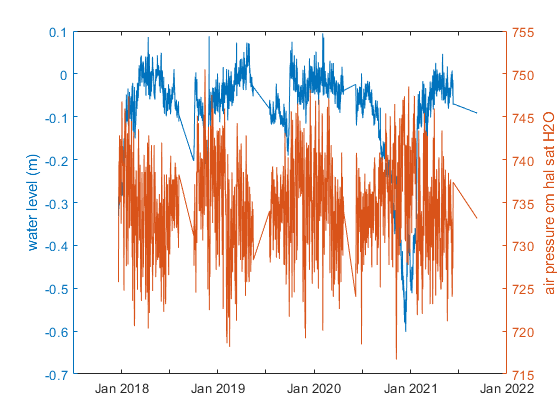

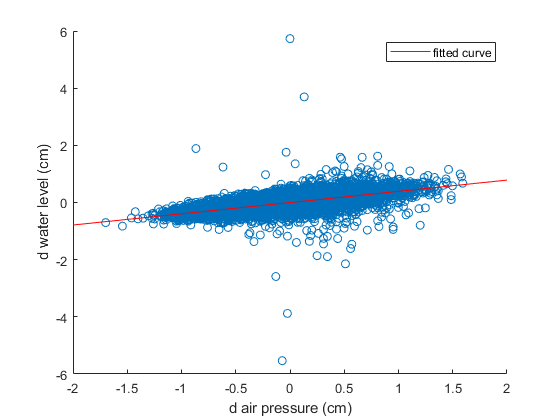

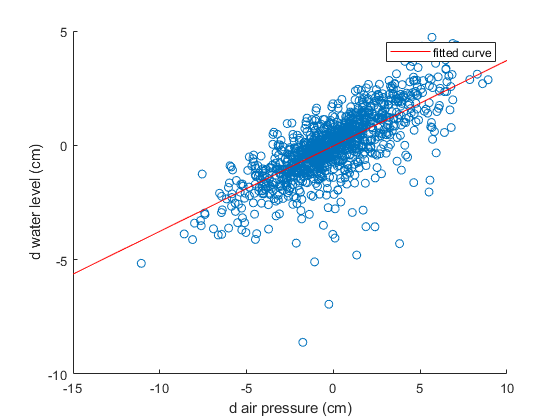

BLM93_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.60722                       0.42189                    0.59094                0.60289                     0.47726                  0.58804           93  


load('BLM93.mat')
BLM93 = WellGradientCalculaton(BLM93, Bflat30min);
BLM93_BaroEff = BaroEff(BLM93, 93)

%%Correction to BLM93 DTW values
BLM93_BaroEff.BaroEff = mean(table2array(BLM93_BaroEff(1,[1 3 4 6])))

BLM93_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.60722                       0.42189                    0.59094                0.60289                     0.47726                  0.58804           93      0.59727


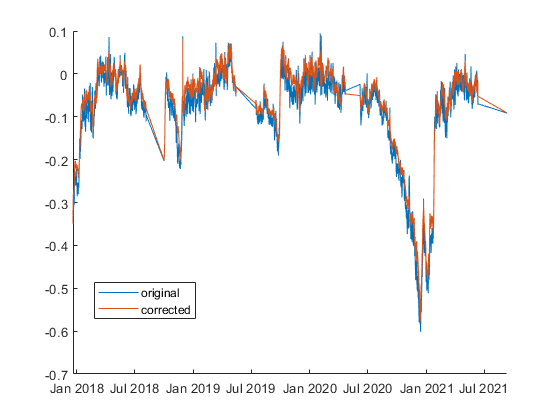

BLM93 =  BaroCorrection(BLM93, BLM93_BaroEff.BaroEff);

## BLM93A Barometric Efficiency

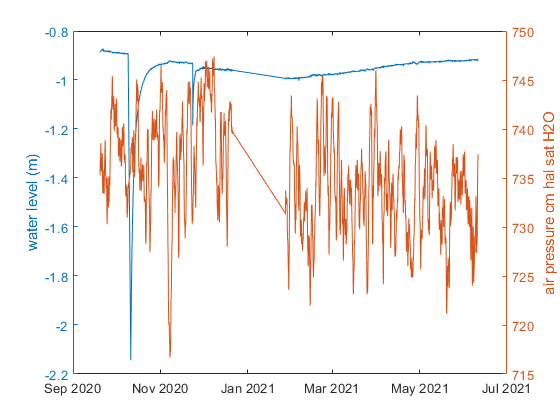

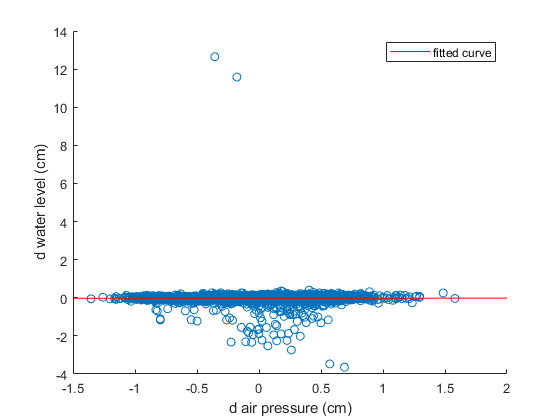

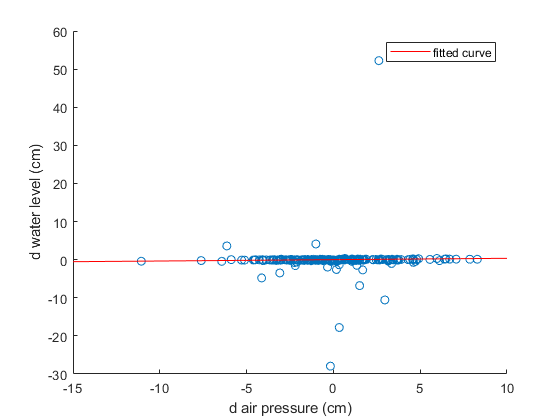

BLM93A_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.99897                     1.6881e-06                   0.97411                0.93336                    0.027341                  0.98481          93.1 


load('BLM93A.mat')
BLM93A = WellGradientCalculaton(BLM93A,Bflat30min);
BLM93A_BaroEff = BaroEff(BLM93A , 93.1)

%%Correction to BLM93 DTW values
BLM93A_BaroEff.BaroEff = mean(table2array(BLM93A_BaroEff(1,[1 3 4 6])))

BLM93A_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.99897                     1.6881e-06                   0.97411                0.93336                    0.027341                  0.98481          93.1     0.97281


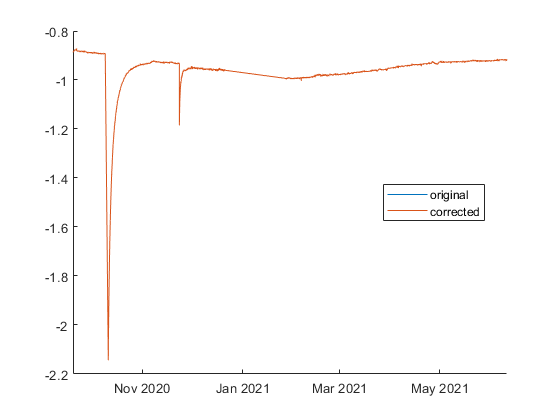

BLM93A_BaroEff.BaroEff = 1;
BLM93A =  BaroCorrection(BLM93A, BLM93A_BaroEff.BaroEff);

## BLM64 Barometric Efficiency

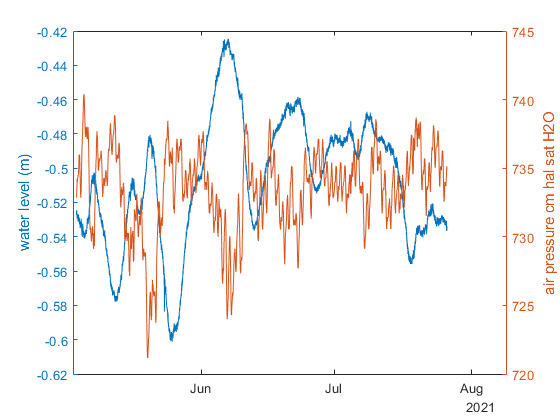

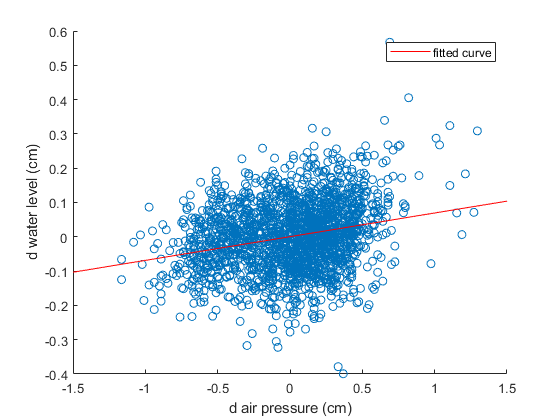

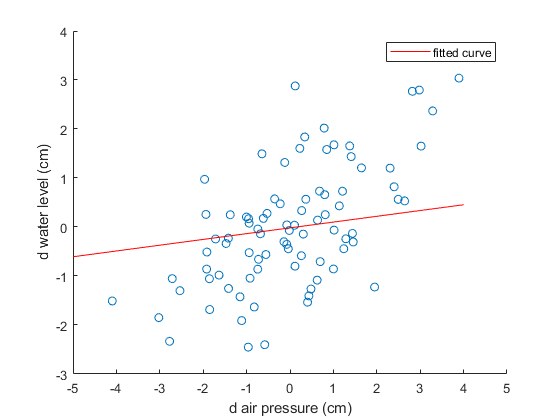

BLM64_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.93092                       0.06205                    0.95019                0.50634                     0.21202                  0.61163           64  


load("BLM64.mat")
BLM64 = WellGradientCalculaton(BLM64,Bflat30min);
BLM64_BaroEff = BaroEff(BLM64 , 64)

%%Correction to BLM93 DTW values
BLM64_BaroEff.BaroEff = mean(table2array(BLM64_BaroEff(1,[1 3]))) %high effieciency - air pressure not the main thing controlling these levels - faulty TD?

BLM64_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.93092                       0.06205                    0.95019                0.50634                     0.21202                  0.61163           64      0.94056


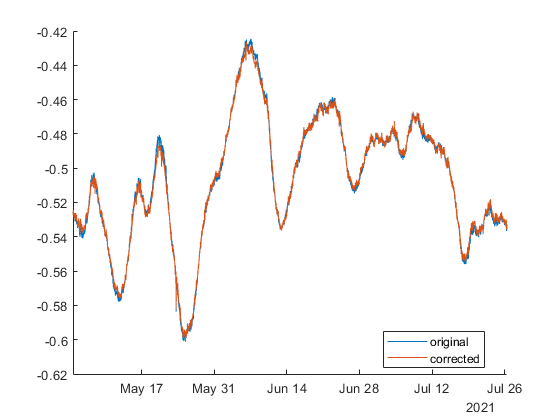

BLM64 =  BaroCorrection(BLM64, BLM64_BaroEff.BaroEff);

## BLM63 Barometric Efficiency

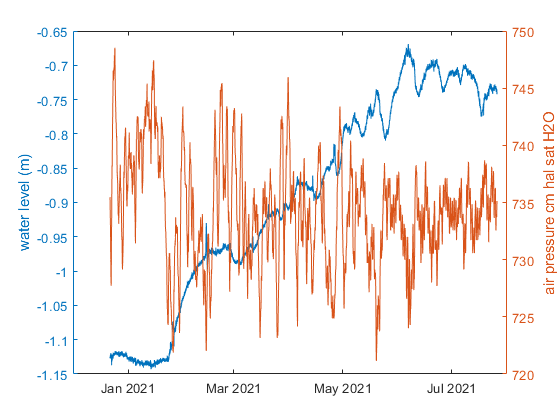

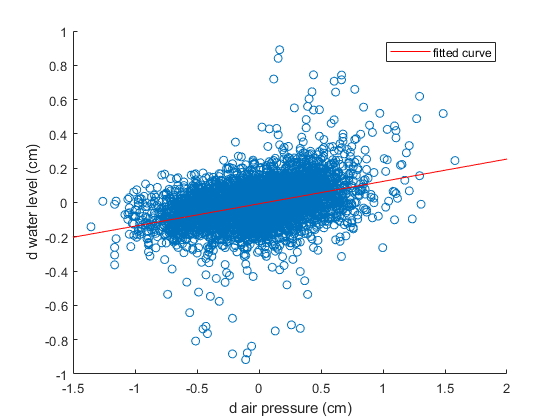

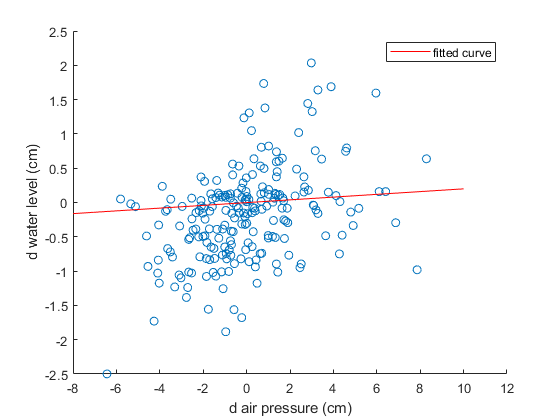

BLM63_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.86967                       0.15323                    0.88449                0.88875                    0.0082253                 0.90875           63  


load("BLM63.mat")
BLM63 = WellGradientCalculaton(BLM63,Bflat30min);
BLM63_BaroEff = BaroEff(BLM63 , 63)

%%Correction to BLM63 DTW values 
BLM63_BaroEff.BaroEff = mean(table2array(BLM63_BaroEff(1,[6])))

BLM63_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.86967                       0.15323                    0.88449                0.88875                    0.0082253                 0.90875           63      0.90875


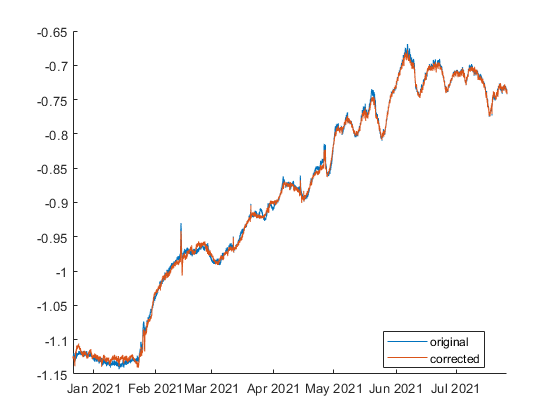

BLM63 =  BaroCorrection(BLM63, BLM63_BaroEff.BaroEff);

## BLM53B Barometric Efficiency

load('BLM53B.mat')
BLM53B = WellGradientCalculaton(BLM53B,Bflat30min)

BLM53B = 10409×10 timetable
       Date_Time_MDT        WaterTemp_C    WaterLevelBelowSurface_m    TDdepth_m    EquivalentHead_HaliteSaturated_BelowSurf_m    Pressure_kPa    AirTemp1_C    SoilTemp_C    Pressure_H2O_1211kgm3density    gradient_pressure    gradient_waterlevel
    ____________________    ___________    ________________________    _________    __________________________________________    ____________    __________    __________    ____________________________    _________________    ___________________

    12/21/20 03:30:00 PM      11.528               0.71401               2.882        

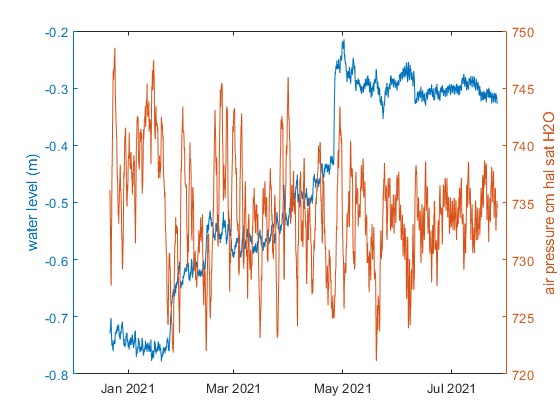

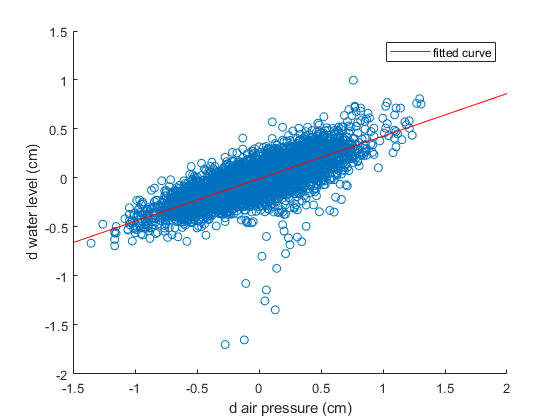

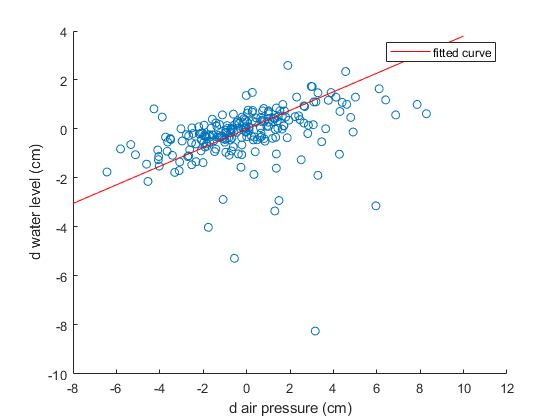

BLM53B_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

            0.5656                       0.59114                    0.56606                0.84871                     0.61252                  0.79313          53.2 


BLM53B_BaroEff = BaroEff(BLM53B , 53.2) %well located next to collection ditch can see some period where negative water level change with no air pressure change

%%Correction to BLM53B DTW values 
BLM53B_BaroEff.BaroEff = mean(table2array(BLM53B_BaroEff(1,[4 6])))

BLM53B_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

            0.5656                       0.59114                    0.56606                0.84871                     0.61252                  0.79313          53.2     0.82092


BLM53B_BaroEff.BaroEff = mean(table2array(BLM53B_BaroEff(1,[1 3 4 6])))

BLM53B_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

            0.5656                       0.59114                    0.56606                0.84871                     0.61252                  0.79313          53.2     0.69337


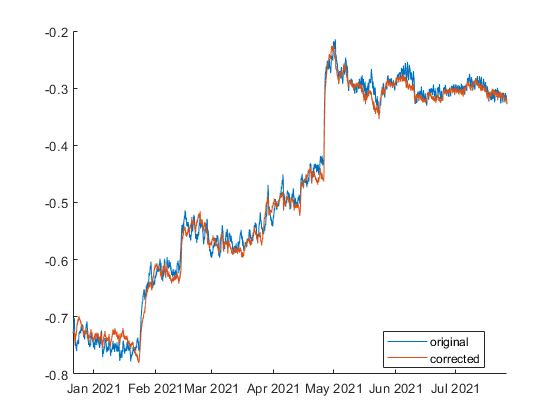

BLM53B =  BaroCorrection(BLM53B, BLM53B_BaroEff.BaroEff);

## BLM53 Barometric Efficiency

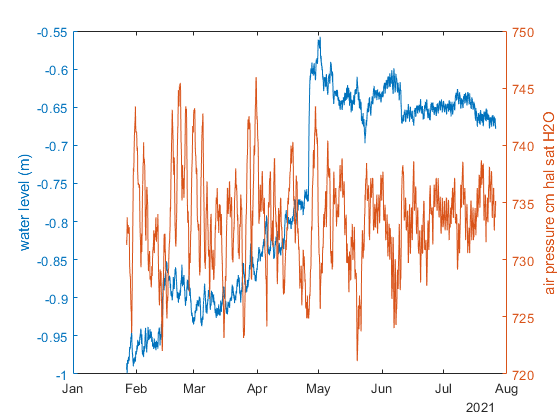

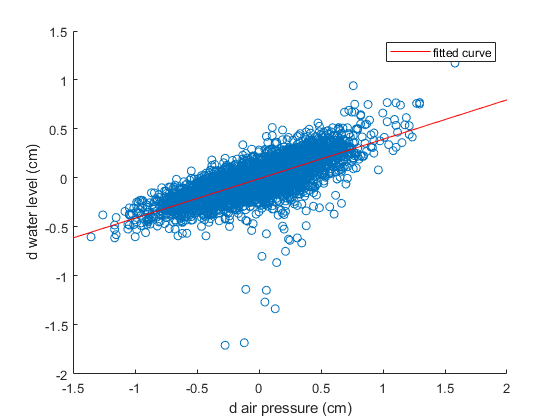

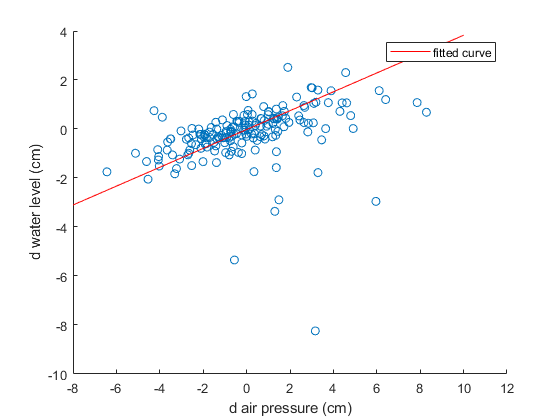

BLM53_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.59732                       0.55566                    0.60876                0.84325                     0.61783                  0.76883           53  


load('BLM53.mat')
BLM53 = WellGradientCalculaton(BLM53,Bflat30min);
BLM53_BaroEff = BaroEff(BLM53 , 53)

%%Correction to BLM53 DTW values 
BLM53_BaroEff.BaroEff = mean(table2array(BLM53_BaroEff(1,[1 3 4 6])))

BLM53_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.59732                       0.55566                    0.60876                0.84325                     0.61783                  0.76883           53      0.70454


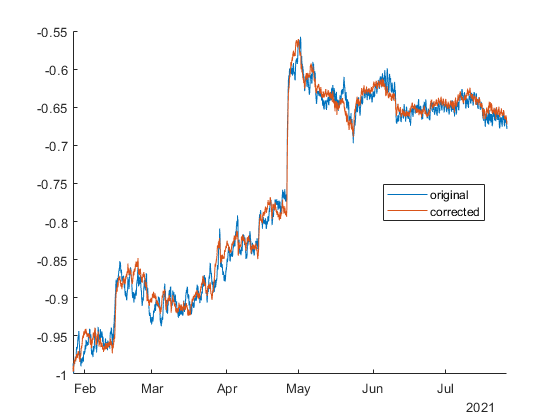

BLM53 =  BaroCorrection(BLM53, BLM53_BaroEff.BaroEff);

## BLM50B Barometric Efficiency

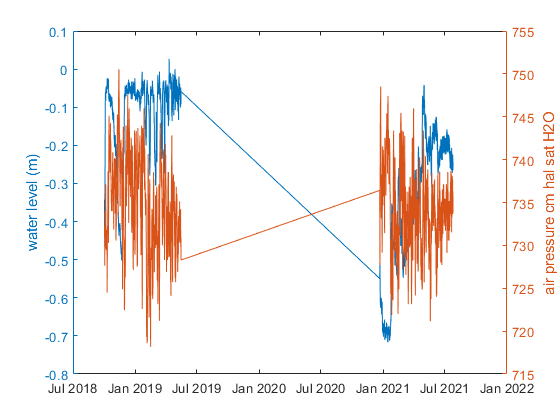

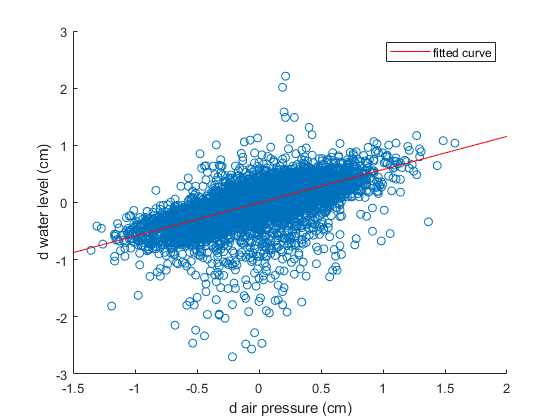

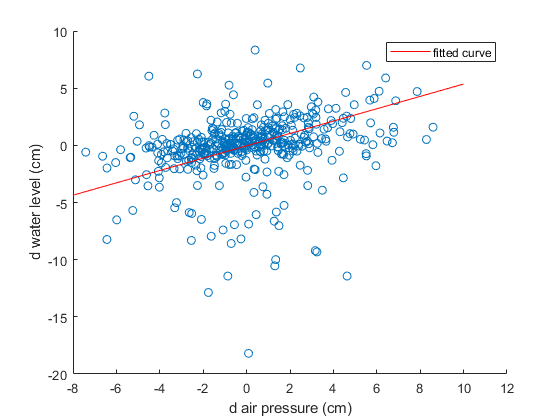

BLM50B_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.41911                       0.40775                    0.41082                0.74963                     0.18703                  0.78093          50.2 


load('BLM50B')
BLM50B = WellGradientCalculaton(BLM50B,Bflat30min);
BLM50B_BaroEff = BaroEff(BLM50B , 50.2)

%%Correction to BLM50B DTW values 
BLM50B_BaroEff.BaroEff = mean(table2array(BLM50B_BaroEff(1,[1 3 4 6])))

BLM50B_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.41911                       0.40775                    0.41082                0.74963                     0.18703                  0.78093          50.2     0.59012


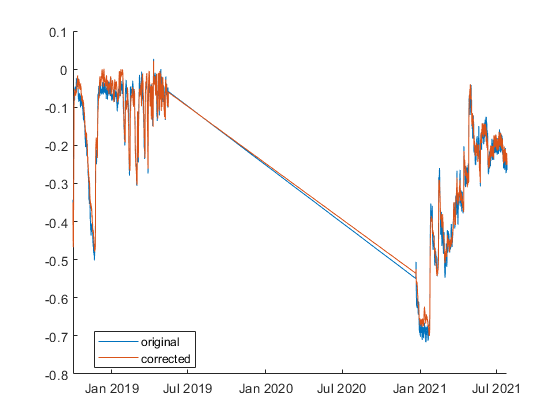

BLM50B =  BaroCorrection(BLM50B, BLM50B_BaroEff.BaroEff);

## BLM45 Barometric Efficiency

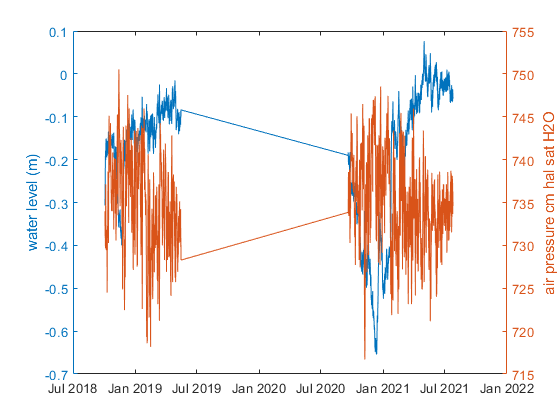

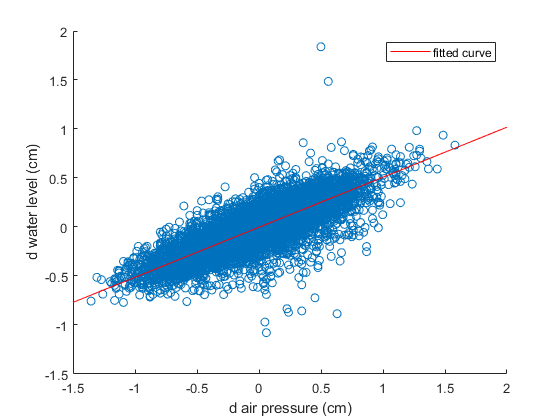

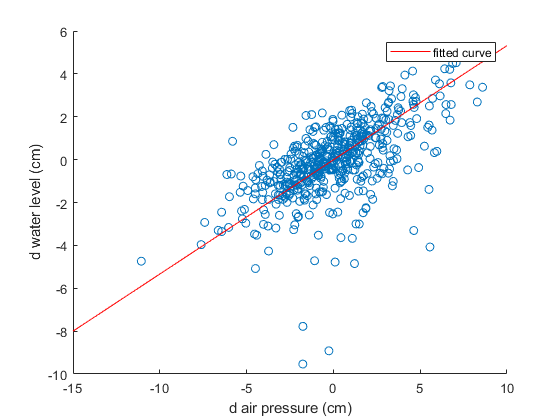

BLM45_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.48922                       0.67247                    0.45979                0.62297                     0.61993                  0.60166           45  


load("BLM45.mat")
BLM45 = WellGradientCalculaton(BLM45,Bflat30min);
BLM45_BaroEff = BaroEff(BLM45, 45)

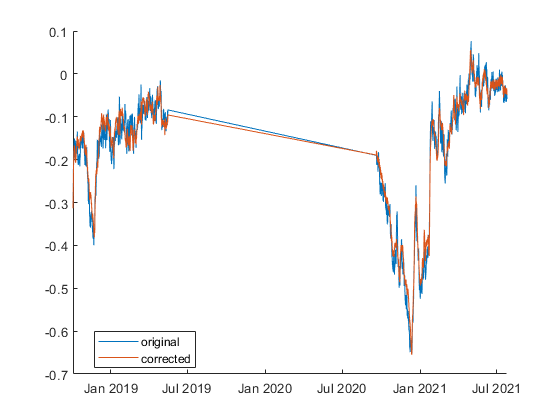

%%Correction to BLM45 DTW values 
BLM45_BaroEff.BaroEff = mean(table2array(BLM45_BaroEff(1,[1 3 4 6])));
BLM45 =  BaroCorrection(BLM45, BLM45_BaroEff.BaroEff);

## BLM43A Barometric Efficiency

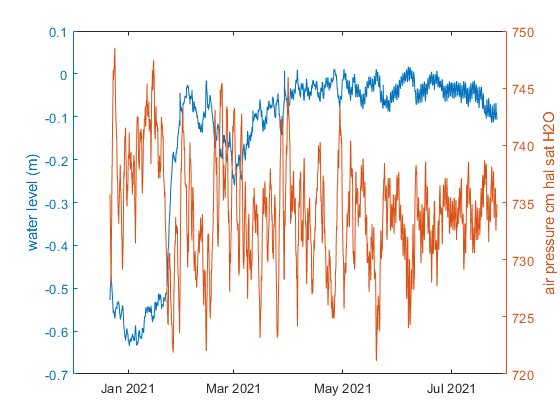

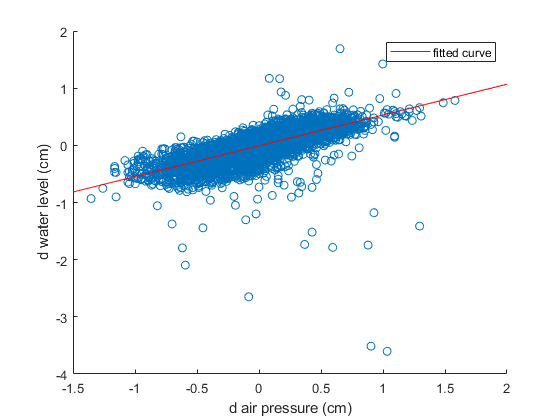

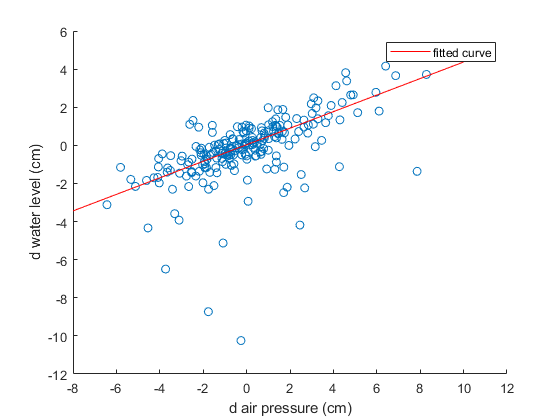

BLM43A_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.46118                       0.48322                    0.42397                0.59747                     0.70686                  0.60456          43.1 


load('BLM43A.mat')
BLM43A = WellGradientCalculaton(BLM43A,Bflat30min);
BLM43A_BaroEff = BaroEff(BLM43A, 43.1)

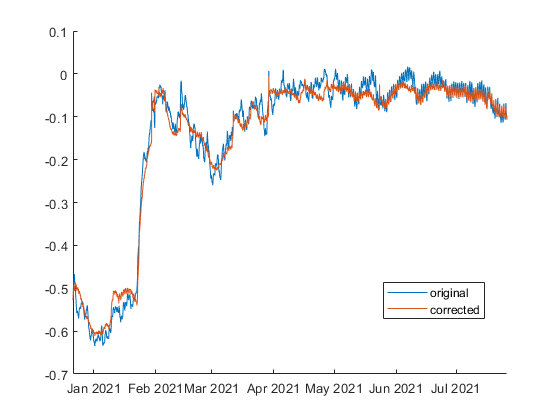

%%Correction to BLM43A DTW values 
BLM43A_BaroEff.BaroEff = mean(table2array(BLM43A_BaroEff(1,[1 3 4 6])));
BLM43A =  BaroCorrection(BLM43A, BLM43A_BaroEff.BaroEff);

## BLM41 Barometric Efficiency

load('BLM41.mat')
BLM41 = WellGradientCalculaton(BLM41,Bflat30min)

BLM41 = 29988×10 timetable
       Date_Time_MDT        WaterLevelBelowSurface_m    WaterTemp_C    TDdepth_m    EquivalentHead_HaliteSaturated_BelowSurf_m    Pressure_kPa    AirTemp1_C    SoilTemp_C    Pressure_H2O_1211kgm3density    gradient_pressure    gradient_waterlevel
    ____________________    ________________________    ___________    _________    __________________________________________    ____________    __________    __________    ____________________________    _________________    ___________________

    12/18/17 09:30:00 PM            0.69473               10.846         2.54          

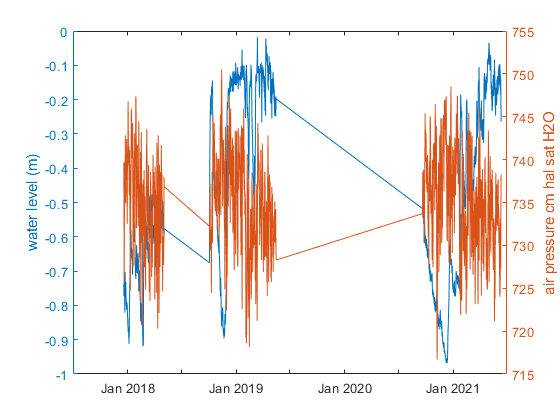

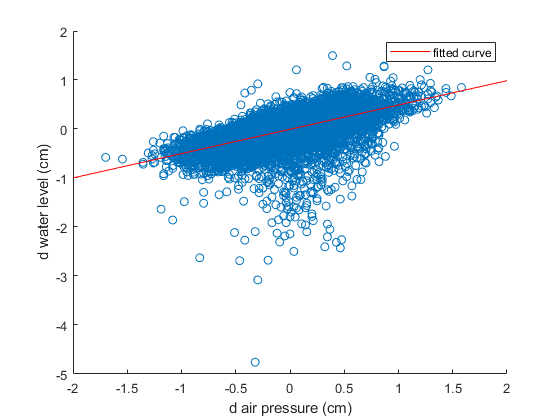

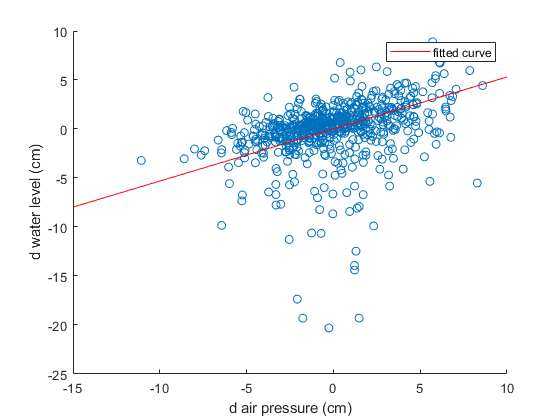

BLM41_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.50379                       0.33792                    0.51539                0.6527                      0.24714                  0.73121           41  


BLM41_BaroEff = BaroEff(BLM41, 41)

%%Correction to BLM41 DTW values 
BLM41_BaroEff.BaroEff = mean(table2array(BLM41_BaroEff(1,[4 6])))

BLM41_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.50379                       0.33792                    0.51539                0.6527                      0.24714                  0.73121           41      0.60077


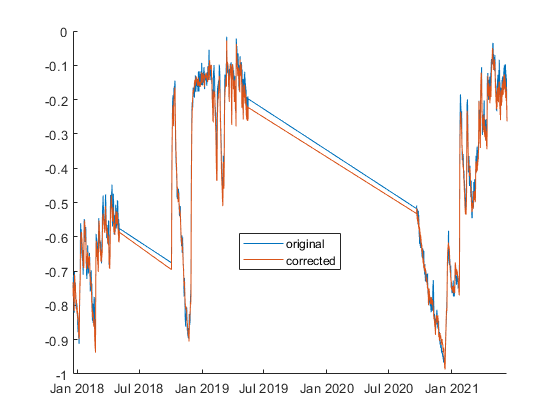

BLM41 =  BaroCorrection(BLM41, BLM41_BaroEff.BaroEff);

## BLM37 Barometric Efficiency 

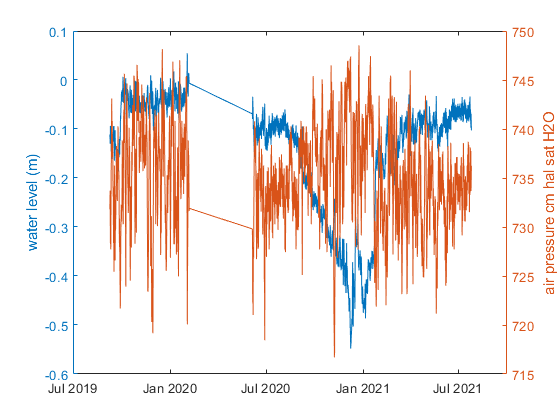

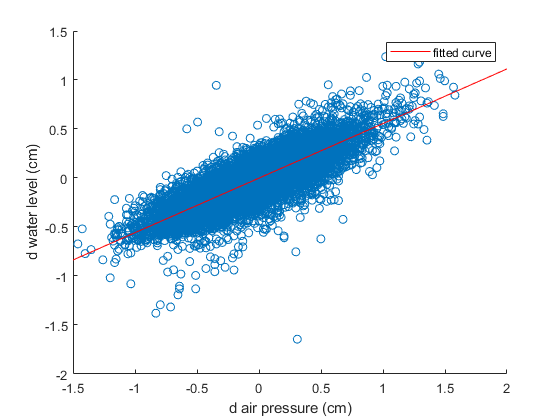

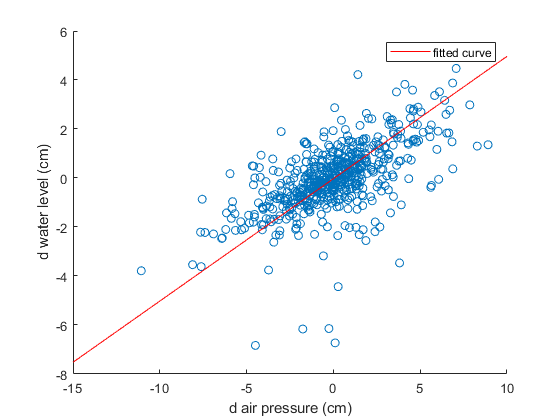

load('BLM37.mat')
BLM37 = WellGradientCalculaton(BLM37,Bflat30min);
BLM37_BaroEff = BaroEff(BLM37, 37);

%%Correction to BLM37 DTW values 
BLM37_BaroEff.BaroEff = mean(table2array(BLM37_BaroEff(1,[1 3 4 6])))

BLM37_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.44301                       0.67302                    0.42478                0.69448                     0.57265                  0.68097           37      0.56081


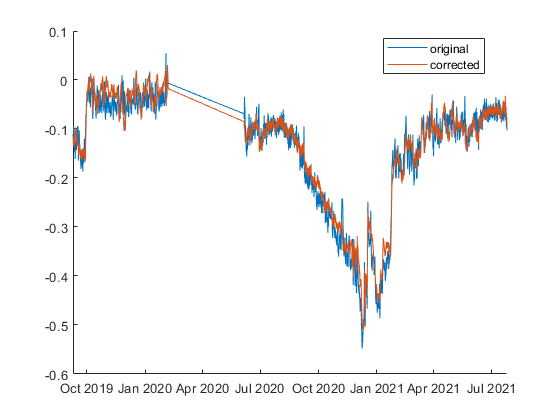

%%doing just 1:2 made the changes more exaggerated than using all, well
%%sensitive to dirunal temperature fluctuations
BLM37 =  BaroCorrection(BLM37, BLM37_BaroEff.BaroEff);

## BLM34 Barometric Efficiency

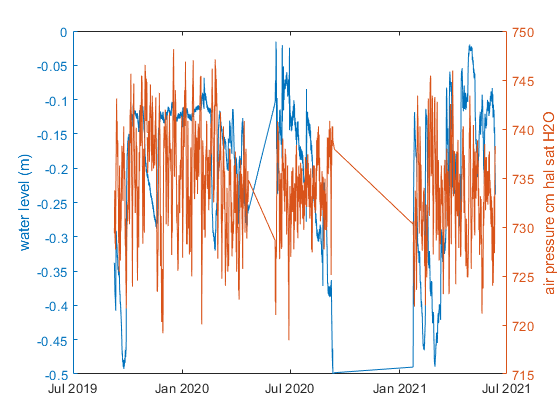

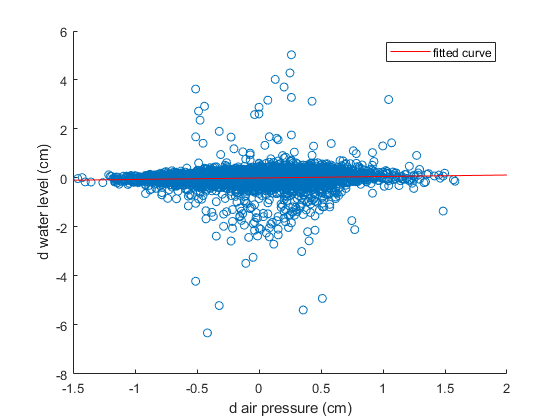

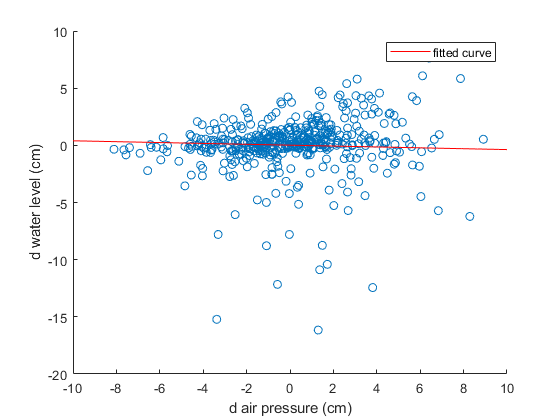

BLM34_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.93952                      0.0062983                   0.94058                0.8928                     0.0053824                 0.91084           34  


load("BLM34.mat")
BLM34 = BLM34(BLM34.EquivalentHead_HaliteSaturated_BelowSurf_m < 0.5 , :);
BLM34 = WellGradientCalculaton(BLM34,Bflat30min);
BLM34_BaroEff = BaroEff(BLM34, 34)

%%Correction to BLM34 DTW values 
load("BLM34.mat")
BLM34 = WellGradientCalculaton(BLM34,Bflat30min);
mean(table2array(BLM34_BaroEff(1,[1 3 4 6])))

ans = 0.9209

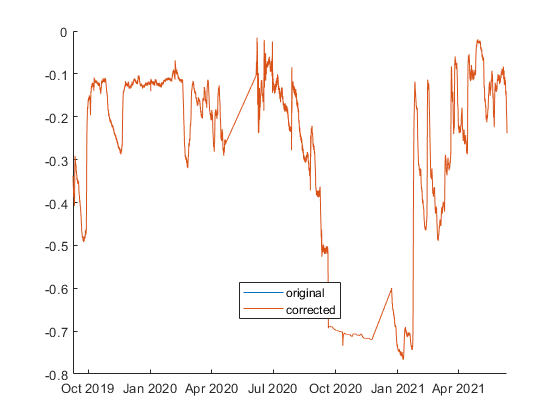

% BLM34_BaroEff.BaroEff = mean(table2array(BLM34_BaroEff(1,[1 3 4 6])));
BLM34_BaroEff.BaroEff = 1;
BLM34 =  BaroCorrection(BLM34, BLM34_BaroEff.BaroEff);

## BLM31 Barometric Efficiency

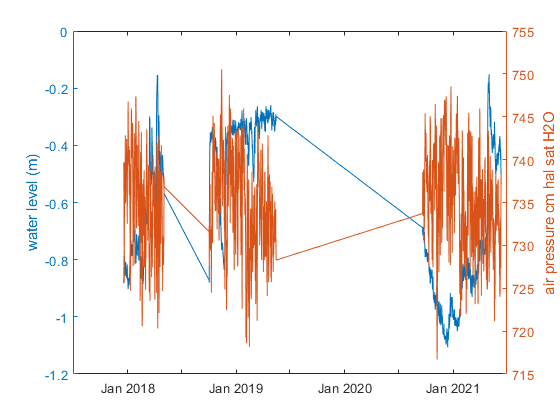

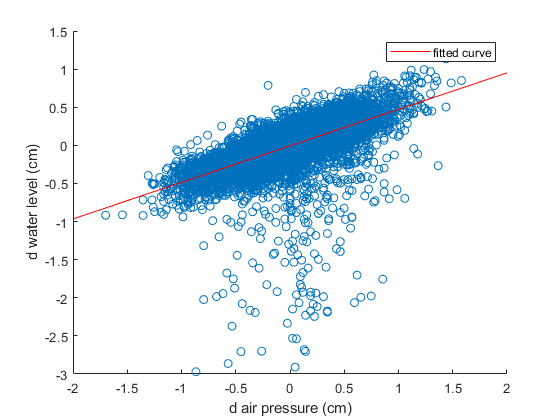

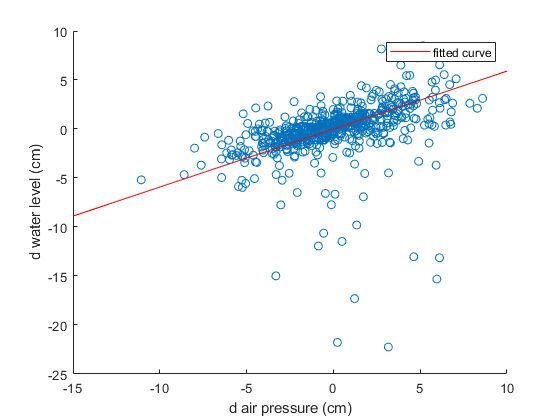

BLM31_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.52079                       0.42351                    0.51513                0.62703                     0.78506                  0.56164           31  


load("BLM31.mat")
BLM31 = WellGradientCalculaton(BLM31,Bflat30min);
BLM31_BaroEff = BaroEff(BLM31, 31)

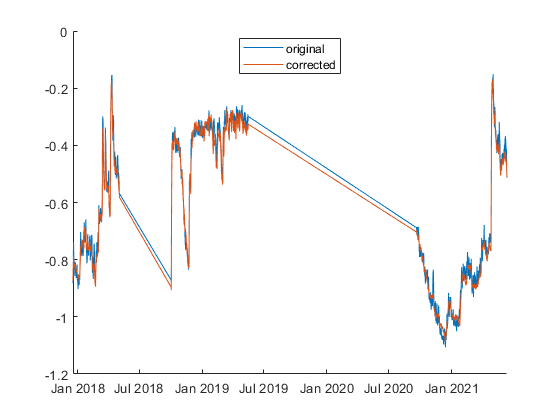

%%Correction to BLM31 DTW values 
BLM31_BaroEff.BaroEff = mean(table2array(BLM31_BaroEff(1,[1 3 4 6])));
BLM31 =  BaroCorrection(BLM31, BLM31_BaroEff.BaroEff);

## BLM16 Barometric Efficiency

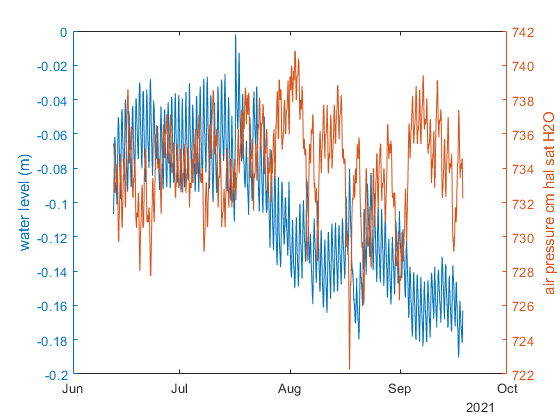

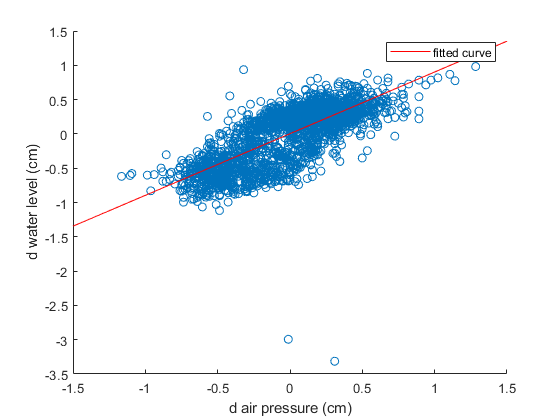

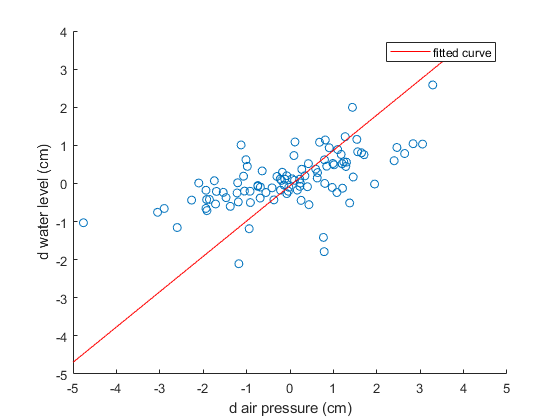

BLM16_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.10093                       0.56475                  -0.00069076              0.6939                      0.68476                  0.69616           16  


load("BLM16.mat")
BLM16 = WellGradientCalculaton(BLM16,Bflat30min);
BLM16_BaroEff = BaroEff(BLM16, 16)

%%Correction to BLM16 DTW values 
BLM16_BaroEff.BaroEff = mean(table2array(BLM16_BaroEff(1,[4 6])))

BLM16_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.10093                       0.56475                  -0.00069076              0.6939                      0.68476                  0.69616           16      0.69503


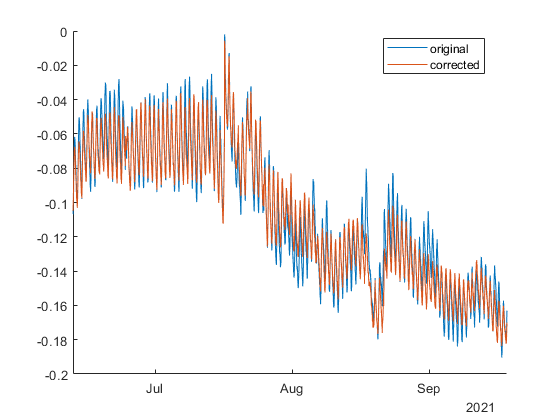

BLM16 =  BaroCorrection(BLM16, BLM16_BaroEff.BaroEff);

## BLM16A Barometric Efficiency

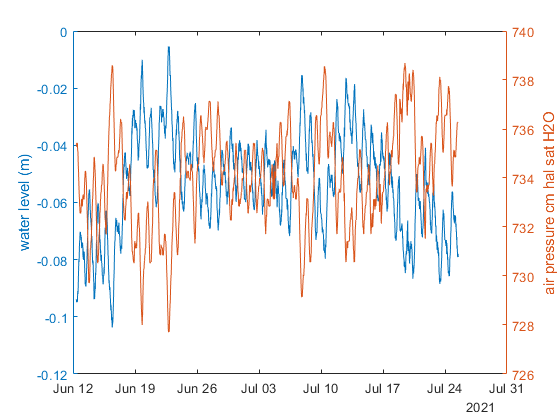

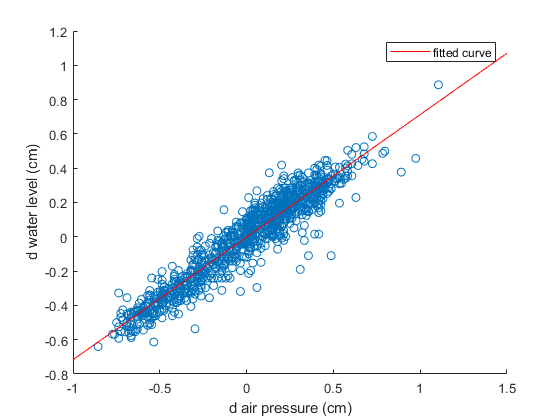

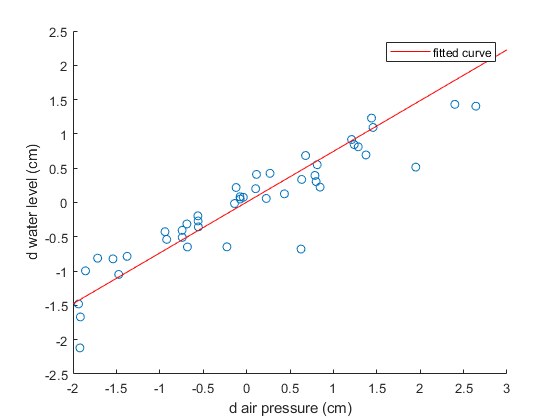

BLM16A_BaroEff = 1×7 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______

           0.28515                       0.89702                    0.26955                0.37833                     0.92925                  0.45834          16.1 


load("BLM16A.mat")
BLM16A = WellGradientCalculaton(BLM16A,Bflat30min);
BLM16A_BaroEff = BaroEff(BLM16A, 16.1)

%%Correction to BLM16A DTW values 
BLM16A_BaroEff.BaroEff = mean(table2array(BLM16A_BaroEff(1, [1 3 4 6])))

BLM16A_BaroEff = 1×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.28515                       0.89702                    0.26955                0.37833                     0.92925                  0.45834          16.1     0.34784


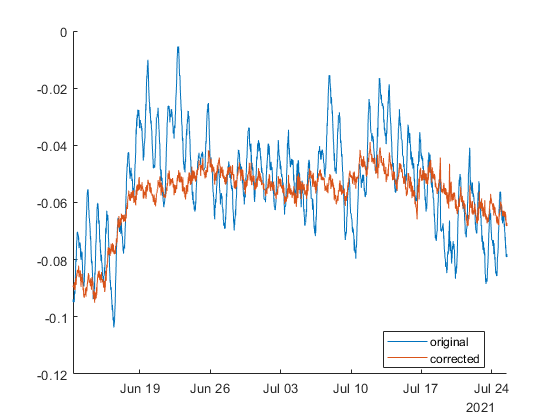

BLM16A =  BaroCorrection(BLM16A, BLM16A_BaroEff.BaroEff);

## BLM12 Barometric Efficiency

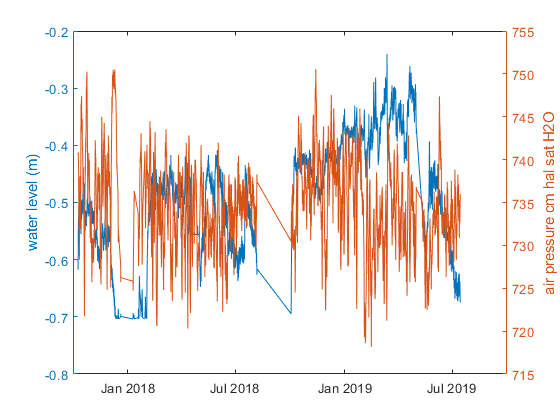

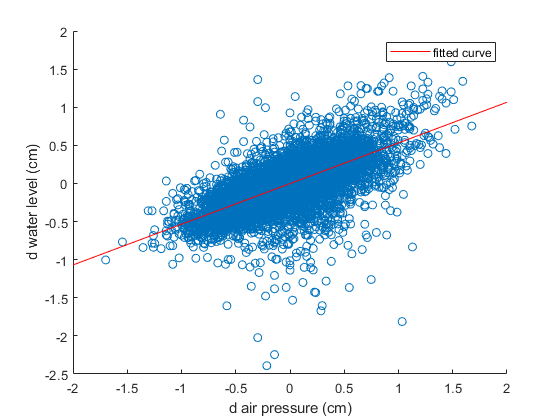

BLM12_BaroEff = 1×3 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly
    ______________________    _____________________________    _________________

           0.46631                       0.46075                    0.44175     


load('BLM12.mat')
  BLM12 = sortrows(BLM12,'WaterLevelBelowSurface_m','ascend');
  
%     BLM12(27044:55298,:) = []; %remove empty rows
       BLM12(50087:end,:) = []; %remove empty rows
      
BLM12 = WellGradientCalculaton(BLM12,Bflat30min);

% BLM12_BaroEff = BaroEff(BLM12, 12)

%%Correction to BLM12 DTW values 
load('BLM12.mat')
BLM12 = WellGradientCalculaton(BLM12,Bflat30min);

% BLM12_BaroEff.BaroEff = mean(table2array(BLM12_BaroEff(1,[1 2])))

BLM12_BaroEff = 1×4 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    BaroEff
    ______________________    _____________________________    _________________    _______

           0.46631                       0.46075                    0.44175         0.46353


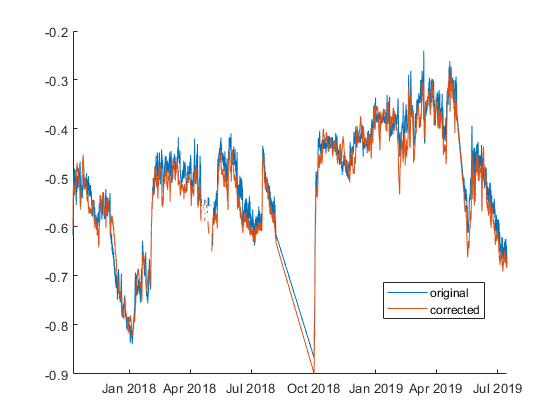

BLM12_BaroEff.BaroEff = 0.6;
BLM12 =  BaroCorrection(BLM12, BLM12_BaroEff.BaroEff);



BLM12_BaroEff.Var5(1) = NaN;
BLM12_BaroEff.Var6(1) = NaN;
BLM12_BaroEff.Var7(1) = 12;
BLM12_BaroEff.Var8(1) = 0.6;

BLM12_BaroEff.Properties.VariableNames{7} = 'WellID';
BLM12_BaroEff.Properties.VariableNames{5} = '2';
BLM12_BaroEff.Properties.VariableNames{4} = 'LinearRegressionDaily';
BLM12_BaroEff.Properties.VariableNames{5} = 'LinearRegressionDailyRquare';
BLM12_BaroEff.Properties.VariableNames{8} = 'BaroEff';



## Create a table of barometric efficiency corrected data

BaroEfficiencySummary = [BLM12_BaroEff; BLM16_BaroEff; BLM16A_BaroEff; BLM31_BaroEff; BLM34_BaroEff; BLM37_BaroEff; BLM41_BaroEff; ...
    BLM45_BaroEff; BLM50B_BaroEff; BLM53B_BaroEff; BLM53_BaroEff; BLM64_BaroEff; BLM63_BaroEff; ...
    BLM93_BaroEff;BLM93A_BaroEff; BLM93C_BaroEff]

BaroEfficiencySummary = 16×8 table
    LinearRegressionHourly    LinearRegressionHourlyRsquare    MedianRatioHourly    LinearRegressionDaily    LinearRegressionDailyRquare    MedianRatioDaily    WellID    BaroEff
    ______________________    _____________________________    _________________    _____________________    ___________________________    ________________    ______    _______

           0.46631                        0.46075                     0.44175                  NaN                          NaN                     NaN            12         0.6
           0.10093                        0.56475                 -0.00069076               0.6939                      0.68476                 0.69616       

# Save barometric efficiency-corrected files

cd ..\output\

save("BaroEfficiencySummary.mat", 'BaroEfficiencySummary')
save('BLM93_AirPresCor.mat', 'BLM93')
save('BLM93C_AirPresCor.mat', 'BLM93C')
save('BLM93A_AirPresCor.mat', 'BLM93A')
save('BLM64_AirPresCor.mat', 'BLM64')
save('BLM63_AirPresCor.mat', 'BLM63')
save('BLM53_AirPresCor.mat', 'BLM53')
save('BLM53B_AirPresCor.mat', 'BLM53B')
save('BLM50B_AirPresCor.mat', 'BLM50B')
save('BLM45_AirPresCor.mat', 'BLM45')
save('BLM43A_AirPresCor.mat', 'BLM43A')
save('BLM41_AirPresCor.mat', 'BLM41')
save('BLM37_AirPresCor.mat', 'BLM37')
save('BLM34_AirPresCor.mat', 'BLM34')
save('BLM31_AirPresCor.mat', 'BLM31')
save('BLM16_AirPresCor.mat', 'BLM16')
save('BLM16A_AirPresCor.mat', 'BLM16A')
save('BLM12_AirPresCor.mat', 'BLM12')

# Figure for supplemental

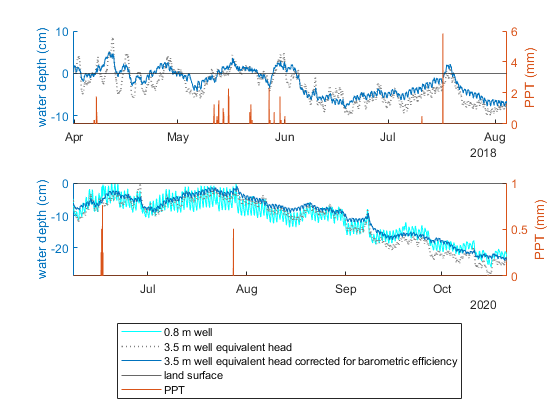

cd ..\input\
load('Bflat30min.mat')
cd ..\output\

figure
tiledlayout 'flow'
nexttile
hold on 
yyaxis left
plot(BLM93.Date_Time_MDT, BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,':','color',[0.5 0.5 0.5],'linewidth',1.2, 'DisplayName','3.5 m well equivalent head')
plot(BLM93.Date_Time_MDT,BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'-','color', [0 0.4470 0.7410],'DisplayName','3.5 m well equivalent head corrected for barometric efficiency')
yline(0, 'displayname', 'land surface')

ylabel('water depth (cm)')
ylim([-12,10])

yyaxis right
plot(Bflat30min.Date_Time_MDT, Bflat30min.PPT_mm, 'color', [0.8500 0.3250 0.0980]);
ylabel('PPT (mm)')

xlim([datetime(2018,3,31,15,1,13)...
      datetime(2018,8,4,9,49,46)])

nexttile
hold on 
yyaxis left
plot(BLM93C.Date_Time_MDT, BLM93C.WaterLevelBelowSurface_m*-100, 'color',	[0 1 1], 'DisplayName','0.8 m well')
plot(BLM93.Date_Time_MDT, BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,':','color',[0.5 0.5 0.5],'linewidth',1.2, 'DisplayName','3.5 m well equivalent head')
plot(BLM93.Date_Time_MDT,BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'-','color', [0 0.4470 0.7410],'DisplayName','3.5 m well equivalent head corrected for barometric efficiency')
yline(0, 'displayname', 'land surface')
ylabel('water depth (cm)')

yyaxis right
plot(Bflat30min.Date_Time_MDT, Bflat30min.PPT_mm, 'color', [0.8500 0.3250 0.0980], 'DisplayName','PPT');
ylabel('PPT (mm)')

xlim([datetime(2020,6,07,15,1,13)...
      datetime(2020,10,21,9,49,46)])

legend('Location','southoutside')
print('AirPressureCorrectionSupPlot', '-bestfit','-dpdf') %'-bestfit' -fillpage

function well = WellGradientCalculaton(well,Bflat30min)
well = removevars(well, {'WellID_BLM'});
well = innerjoin(well,Bflat30min);
well.Pressure_H2O_1211kgm3density = well.Pressure_kPa*10.1974/1.211;
well.gradient_pressure = gradient(well.Pressure_H2O_1211kgm3density); %linear fit for barometric efficiency
well.gradient_waterlevel = gradient(well.EquivalentHead_HaliteSaturated_BelowSurf_m);
end 

function well =  BaroCorrection(well, BaroEff)
well.gradient_pressure = gradient(well.Pressure_H2O_1211kgm3density)*(1-BaroEff); %linear fit for barometric efficiency - see external table
well.gradient_pressure_cumsum = cumsum(well.gradient_pressure, 'omitnan');
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ((well.gradient_pressure_cumsum + well.EquivalentHead_HaliteSaturated_BelowSurf_m*-100) -mean(well.gradient_pressure_cumsum)/2)/-100; %4 is the shift to offset the correction, so more reflective
well = removevars(well, {'Pressure_kPa','Pressure_H2O_1211kgm3density','gradient_pressure','gradient_waterlevel','gradient_pressure_cumsum'});
figure
hold on
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m, 'DisplayName','original')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'DisplayName','corrected')
xlim(well.Date_Time_MDT([1,end]))
legend('Location',"best")
end

function well_BaroEff = BaroEff(well, wellIDnum)
figure
yyaxis left
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m)
ylabel('water level (m)')
yyaxis right
plot(well.Date_Time_MDT, well.Pressure_H2O_1211kgm3density)
ylabel('air pressure cm hal sat H2O')

wellhourly  = retime(well, 'hourly', 'mean');
wellhourly.gradient_pressure = gradient(wellhourly.Pressure_H2O_1211kgm3density); %linear fit for barometric efficiency
wellhourly.gradient_waterlevel = gradient(wellhourly.EquivalentHead_HaliteSaturated_BelowSurf_m);

### Linear regression determination

idxValid = ~isnan(wellhourly.gradient_pressure);
poly = polyfit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 1);

well_BaroEff(1) = 1 - poly(1);

[fitting, error] = fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1');
well_BaroEff(2) = error.rsquare;

% figure

figure
hold on
scatter(wellhourly.gradient_pressure, wellhourly.gradient_waterlevel*100)
plot(fitting)
% plot(fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1'))
xlabel('d air pressure (cm)')
ylabel('d water level (cm)')

## Median ratio method

wellhourly.dwdb = ((wellhourly.gradient_waterlevel*100)./wellhourly.gradient_pressure);
well_BaroEff(3) = 1 - median(wellhourly.dwdb, 'omitnan');

# Daily Values

welldaily = retime(well, 'daily', 'mean');
welldaily.gradient_pressure = gradient(welldaily.Pressure_H2O_1211kgm3density); %linear fit for barometric efficiency
welldaily.gradient_waterlevel = gradient(welldaily.EquivalentHead_HaliteSaturated_BelowSurf_m);

### Linear regression determination

idxValid = ~isnan(welldaily.gradient_pressure);
poly = polyfit(welldaily.gradient_pressure(idxValid), welldaily.gradient_waterlevel(idxValid)*100, 1);
well_BaroEff(4) = 1 - poly(1);
[fitting, error] = fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1');
well_BaroEff(5) = error.rsquare;

figure
hold on
scatter(welldaily.gradient_pressure, welldaily.gradient_waterlevel*100)
plot(fitting)
% plot(fit(welldaily.gradient_pressure(idxValid), welldaily.gradient_waterlevel(idxValid)*100, 'poly1'))
xlabel('d air pressure (cm)')
ylabel('d water level (cm)')

## Median ratio method

welldaily.dwdb = ((welldaily.gradient_waterlevel*100)./welldaily.gradient_pressure);
well_BaroEff(6) = 1 - median(welldaily.dwdb, 'omitnan');
well_BaroEff(7) = wellIDnum;

well_BaroEff = array2table(well_BaroEff);


well_BaroEff.Properties.VariableNames{1} = 'LinearRegressionHourly';
well_BaroEff.Properties.VariableNames{2} = 'LinearRegressionHourlyRsquare';
well_BaroEff.Properties.VariableNames{3} = 'MedianRatioHourly';
well_BaroEff.Properties.VariableNames{4} = 'LinearRegressionDaily';
well_BaroEff.Properties.VariableNames{5} = 'LinearRegressionDailyRquare';
well_BaroEff.Properties.VariableNames{6} = 'MedianRatioDaily';
well_BaroEff.Properties.VariableNames{7} = 'WellID';

end